## **In the name of God**

# Digital Communication

# Computer Assignment #3

# **Alireza Javid**

# **810198375**

In this assignment for generating raised cosine pulses, We used RC_pulse function which we designed in previous assignment.

% Section 1: Raised-Cosine Pulse Generation

B = 0; 
T = 1;
Fs = 10;
Ts = 1;
L = T*Fs;
[~, RC] = RC_pulse(T, Fs, B, 0, -6, 6);

For modulated symbols, We used random number generation in the interval (0, 1) and in the intervals mentioned in the question. Next using convolution with raised cosine pulses, and then adding AWGN, ‘received_signal’ was created.

% Section 2: Creating Modulated Symbols

N = 1e6;

bits = rand(1,N);
SNR_dB = 0:10;

SNR = zeros(1,length(SNR_dB)) ;

modulated_symbols = modulate(bits);

Sampling is done and sampled points of the received signal are saved in samples.  

% Section 3: Transmission and Reception

upsampled_symbols = upsample(modulated_symbols,L);
upsampled_symbols = upsampled_symbols(1:end-(L-1));
transmitted_signal = conv(upsampled_symbols,RC);
noise = randn(1,length(transmitted_signal));

SNR_dB = 0:10;
snr = 10.^(SNR_dB./10);
eta = var(transmitted_signal)./snr;
noise = diag(sqrt(eta./2))*repmat(noise,11,1);
received_signal = repmat(transmitted_signal,11,1)+ noise;

ML Estimation  Detector

For ML Estimation we can use our method in MAP estimation, but prior probability between samples are equal $\frac{1}{M}$ .


$$$$
P_e = \frac{1}{4} Pr\{\hat{A_m} \neq A | A_m = -A\} + \frac{1}{4} Pr\{\hat{A_m} \neq B | A_m = B\}
$$
$$
+ \frac{1}{4} Pr\{\hat{A_m} \neq C | A_m = C\} + \frac{1}{4} Pr\{\hat{A_m} \neq D | A_m = D\}
$$
$$
P_e = \frac{1}{4} \bigg( Pr\{Y(t_m) > {\Delta}_1 | A_m = A\} + Pr\{ (Y(t_m) > {\Delta}_1)  \cup (Y(t_m) < {\Delta}_2)| A_m = B\}
$$
$$
+ Pr\{ (Y(t_m) > {\Delta}_2)  \cup (Y(t_m) < {\Delta}_3)| A_m = C\} + Pr\{ Y(t_m) > {\Delta}_3 | A_m = C\} \bigg)
$$
$$
P_e = \frac{1}{4} \bigg( Pr\{n(t_m) > {\Delta}_1 + 3\} + Pr\{ (n(t_m) > {\Delta}_1 + 1)  \cup (Y(t_m) < {\Delta}_2 + 1)\}
$$
$$
+ Pr\{ (n(t_m) > {\Delta}_2 - 1)  \cup (n(t_m) < {\Delta}_3) - 1\} + Pr\{ n(t_m) > {\Delta}_3 - 3 \} \bigg)
$$
$$
P_e = \frac{1}{4} \bigg( Q\big(\frac{{\Delta}_1 + 3}{N_0}\big) + Q\big(\frac{{-\Delta}_1 - 1}{N_0}\big) + Q\big(\frac{{\Delta}_2 + 1}{N_0}\big) + Q\big(\frac{{-\Delta}_2 + 1}{N_0}\big) + Q\big(\frac{{\Delta}_3 - 1}{N_0}\big)+ Q\big(\frac{-{\Delta}_3 + 3}{N_0}\big) \bigg)
$$$$


As prior probability between samples are equal, we have **symmetry** between samples 

and for optimal thresholds we can say:


$${\Delta}_1 = -2 \quad,\quad {\Delta}_2 = 0 \quad, \quad {\Delta}_3 = 2$$


Substituting results in Error probability formula, minimum error probability is achieved  


$$P_{e(ML)} ^{opt} = \frac{3}{2}Q\big(\frac{1}{N_0}\big)
$$


% Section 4: ML detection:
T_sampling = 6*L+1 : L : (N+6-1)*L+1;
samples = received_signal(:,T_sampling);
delta_ml = [-2*ones(1,length(SNR_dB));zeros(1,length(SNR_dB));
    2*ones(1,length(SNR_dB))];
detected_symbols_ML = detect(samples,length(SNR_dB),delta_ml);
error_ML = error_detect(length(SNR_dB), length(detected_symbols_ML) ...
    ,detected_symbols_ML,modulated_symbols);

Pe_ML = reshape(error_ML, [1 11])/N;

MAP Estimation  Detector

First we find $P_e \;$in close form and in terms of thresholds


$$$$
P_e = Pr\{Y(t_m) > {\Delta}_1 | A_m = A\} P_A+ Pr\{ (Y(t_m) > {\Delta}_1)  \cup (Y(t_m) < {\Delta}_2)| A_m = B\} P_B
$$
$$
+ Pr\{ (Y(t_m) > {\Delta}_2)  \cup (Y(t_m) < {\Delta}_3)| A_m = C\} P_C + Pr\{ Y(t_m) > {\Delta}_3 | A_m = C\} P_D
$$
$$
P_e = Pr\{n(t_m) > {\Delta}_1 + 3\} P_A + Pr\{ (n(t_m) > {\Delta}_1 + 1)  \cup (Y(t_m) < {\Delta}_2 + 1)\} P_B
$$
$$
+ Pr\{ (n(t_m) > {\Delta}_2 - 1)  \cup (n(t_m) < {\Delta}_3) - 1\} P_C + Pr\{ n(t_m) > {\Delta}_3 - 3 \} P_D
$$
$$
P_e = P_A Q\big(\frac{{\Delta}_1 + 3}{N_0}\big) +  P_B (Q\big(\frac{{-\Delta}_1 - 1}{N_0}\big) + Q\big(\frac{{\Delta}_2 + 1}{N_0}\big)) +  P_C (Q\big(\frac{{-\Delta}_2 + 1}{N_0}\big) + Q\big(\frac{{\Delta}_3 - 1}{N_0}\big))+ P_D Q\big(\frac{-{\Delta}_3 + 3}{N_0}\big) 
$$$$


Now we find optimal thresholds by derivative in respect  of $\Delta_i$ and equal to 0

(1)


$$$$
\frac{d P_e}{d{\Delta}_1} = \frac{P_A}{\sqrt{2\pi N_0}} e^{\frac{-({\Delta}_1 + 3)^2}{2N_0}} - \frac{P_B}{\sqrt{2\pi N_0}} e^{\frac{-({\Delta}_1 + 1)^2}{2N_0}} = 0
$$
$$
{\Delta}_1 = -2 -\frac{N_0}{2} ln(\frac{P_B}{P_A})
$$$$


(2)


$$$$
\frac{d P_e}{d{\Delta}_2} = \frac{P_B}{\sqrt{2\pi N_0}} e^{\frac{-({\Delta}_2 + 1)^2}{2N_0}} - \frac{P_C}{\sqrt{2\pi N_0}} e^{\frac{-({\Delta}_2 - 1)^2}{2N_0}} = 0
$$
$$
{\Delta}_2 = \frac{N_0}{2} ln(\frac{P_B}{P_C}) 
$$$$


(3)


$$$$
\frac{d P_e}{d{\Delta}_3} = \frac{P_C}{\sqrt{2\pi N_0}} e^{\frac{-({\Delta}_3 - 1)^2}{2N_0}} - \frac{P_D}{\sqrt{2\pi N_0}} e^{\frac{-({\Delta}_3 - 3)^2}{2N_0}} = 0
$$
$$
{\Delta}_3 = 2 -\frac{N_0}{2} ln(\frac{P_D}{P_C})
$$$$


Substituting results in Error probability formula, minimum error probability is achieved:  

$P_A =P_D =0\ldotp 1$                ,            $P_C =P_D =0\ldotp 8$


$${\Delta}_1 = -2 -\frac{N_0}{2} ln(4) \quad, \quad {\Delta}_2 = 0 \quad, \quad {\Delta}_3 = 2 -\frac{N_0}{2} ln(4) $$



$$P_{e(MAP)} ^{opt} = 0.2 Q( \frac{1 -\frac{N_0}{2} ln(4)}{N_0} ) + 0.8 \bigg(0.2 Q( \frac{1 +\frac{N_0}{2} ln(4)}{N_0} ) + 0.2 Q( \frac{1}{N_0})\bigg)$$


% Section 5: MAP detection:

delta_MAP = [-0.5*eta/2*log2(4)-2;
    zeros(1,length(SNR_dB));
    0.5*eta/2*log2(4)+2];
detected_symbols_MAP = detect(samples,length(SNR_dB),delta_MAP);
error_MAP = error_detect(length(SNR_dB), length(detected_symbols_MAP) ...
    ,detected_symbols_MAP,modulated_symbols);
Pe_PAM = reshape(error_MAP, [1 11])/N;

As we can see MAP receiver has less Error probability in all SNR values.

When the SNR increases, error probability become lower.

 The gap between MAP and ML performance shrinks as the prioir probabilities tend towards uniform distribution.  

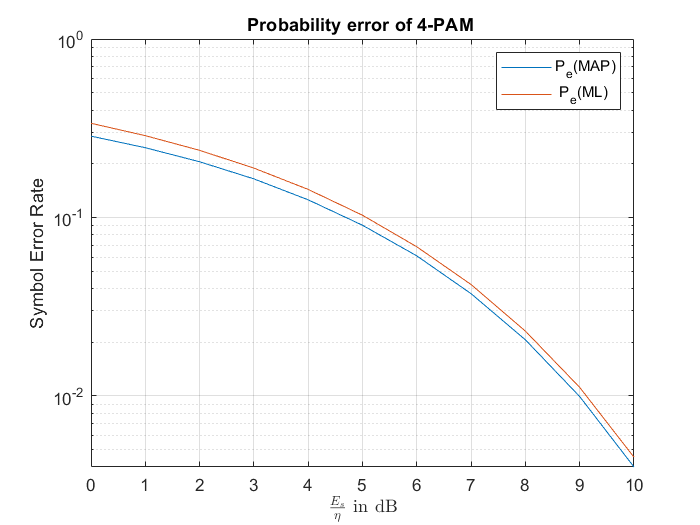

% Section 6: Plotting Results:

figure
semilogy(SNR_dB,Pe_PAM,SNR_dB,Pe_ML)
grid on
title('Probability error of 4-PAM ' )
xlabel('$\frac{E_{s}}{\eta}$ in dB', 'interpreter', 'Latex');
ylabel('Symbol Error Rate')
legend('P_{e}(MAP)',' P_{e}(ML)')

Functions:

function [t , Pulse] = RC_pulse(T, Fs, B, sampling_error, start, ending)

t = (start*Fs:ending*Fs)/Fs-sampling_error;
% display(t)
Pulse = zeros(1,length(t));

for i = 1 : length(t)
   if ( (t(1,i) == -T/(2*B) ) || ( t(1,i) == T/(2*B) ) )
       Pulse(1,i) = (pi/4)*sinc(1/(2*B));
   else 
       Pulse(1,i) = (cos(pi*B*t(1,i)/T).*sinc(t(1,i)/T))./((1-(2*B.*t(1,i)./T).^2));
   end
   
end
end

function [symbols] = modulate(bits)
symbols = zeros(1,length(bits));
for i = 1 : length(bits)   
    if (bits(i)<0.1) && (bits(i)>=0)
        symbols(i) = 3;
    end
    if (bits(i)>=0.1) && (bits(i)<0.5)
        symbols(i) = 1;
    end
    if (bits(i)>=0.5) && (bits(i)<0.9)
        symbols(i) = -1;
    end
    if (bits(i) >= 0.9) && (bits(i) < 1)
        symbols(i) = -3;
    end
end
end
function [symbols] = detect(samples,N,delata)
symbols = zeros(1,length(samples));
for i = 1 : N
    for j = 1 : length(samples)
        if (samples(i,j) <= delata(1,i))
            symbols(i,j) = -3;
        end
        if (samples(i,j) > delata(1,i)) && (samples(i,j) <= delata(2,i))
            symbols(i,j) = -1;
        end
        if (samples(i,j) > delata(2,i)) && (samples(i,j) <= delata(3,i))
            symbols(i,j) = 1;
        end
        if (samples(i,j) > delata(3,i))
            symbols(i,j) = 3;
        end
    end
end
end
function [error] = error_detect(N, M, detected_symbols, modulated_symbols)
error = zeros(1,N);
for i = 1:N
    for j =1:M
        if detected_symbols(i,j) ~= modulated_symbols(j)
            error(i)=error(i)+1;
        end
    end
end

end